## 2D Differentiable Rendering in MATLAB 

This example shows how to perform differentiable vector graphics rendering in MATLAB®. It makes use of *dlarray* for auto-differentiation, and employs signed distance functions and sigmoid smoothing to ensure the rasterization pipeline is continuous and differentiable. First, we look at how to perform differentiable rendering. Then, we use the differentiable rendering pipeline to optimize shape parameters to fit a target image.

### Differentiable Rendering Introduction

Differentiable rendering is a process that allows the computation of gradients through the rasterization pipeline. In traditional rasterization, vector graphics are converted into a raster image (a grid of pixels), but this process is typically non-differentiable due to discontinuities in the rasterization process. Differentiable rasterization, on the other hand, introduces a smooth approximation to this process which enables the computation of gradients with respect to the input parameters of the vector shapes.

Let's look at how we can rasterize a circle in a differentiable way. There are three main steps:

**Step 1.** Let's define the parameters of a circle we want to rasterize into an image. We need the coordinate of the center of the circle and its radius. We will use 'normalized' coordinates, where 0,0 is the top left of the image and 1,1 is the bottom right.

circle_center = [0.5; 0.5];
circle_radius = 0.25;

**Step 2. **Now we will evaluate a *signed distance function* associated with the circle shape. This function calculates the distance to the center of the circle from every pixel in a pre-computer pixel grid. We can then scale this distance by the circles's radius to provide us with an output image where the edges of the circle shape have a value of 1. Note that due to the continuous representation of the coordinates, the edge may not align exactly with a pixel, so there may not be pixels with the exact value of 1 in the image. This is the intended behaviour.

*You might notice that we are essentially evaluating an l2 norm. An easy way to render some different shapes is to try out different norms, e.g., l infinity for a rectangle or l1 for a diamond.*

% Create a 100x100 pixel grid
[Xpixel, Ypixel] = ndgrid(linspace(0,1,100), linspace(0,1,100));

% Signed distance function
dist_to_center = ((Xpixel - circle_center(1)).^2 + (Ypixel - circle_center(2)).^2 )/ circle_radius.^2;

figure
imagesc(dist_to_center)
hold on
% Plot a reference circle on top
h = rectangle('Position',[circle_center(1)*100-circle_radius*100 circle_center(2)*100-circle_radius*100 circle_radius*200 circle_radius*200],'Curvature',[1,1]);
title('Normalized distance to center of the circle')

We know the edges of our rectangle should have a value of 1 in this image, so we could now get our final rasterized image using a logical expression like so:

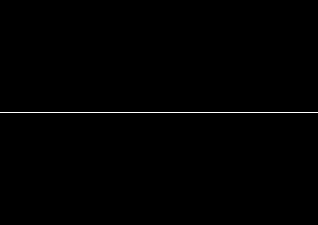

circle_image = dist_to_center<=1;

figure
imshow(circle_image)
title('Rasterized circle')

Which gives us a rasterized circle! However, this is not fully differentiable. Notice that a small change in the parameters, e.g. the position of the circle, will not necessarily change the output image at all if the change is smaller than the size of a pixel. Hence, the gradient will be zero and that is not of use to us.

We can show this by making a small change to the circle's position and plotting the pixel-wise difference between the rasterized images:

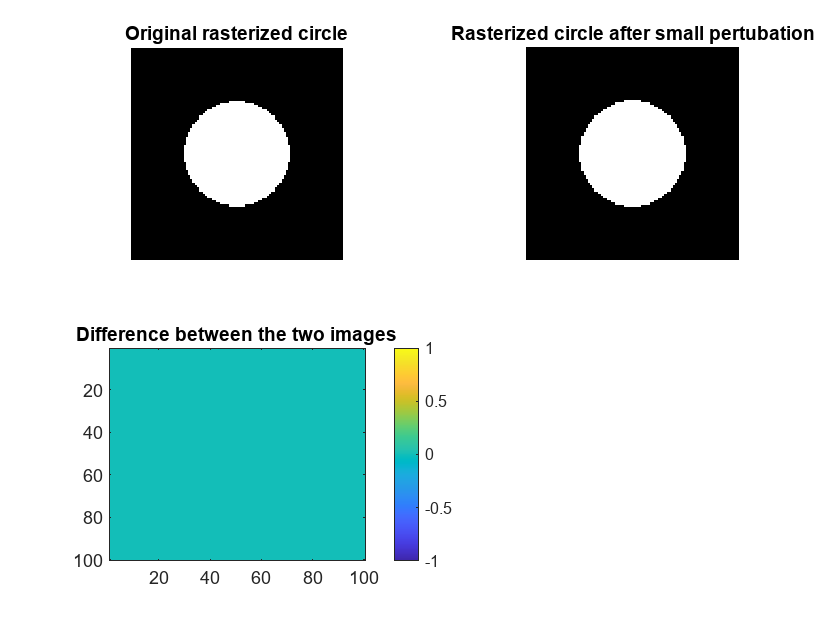

% Make a new circle in a slightly different position
circle_center_changed = circle_center;
circle_center_changed(1) = circle_center(1) + 0.00001;

dist_to_center_changed = ((Xpixel - circle_center_changed(1)).^2 + (Ypixel - circle_center_changed(2)).^2 )/ circle_radius.^2;
circle_image_changed = dist_to_center_changed<=1;

figure
nexttile
imshow(circle_image)
title('Original rasterized circle')
nexttile
imshow(circle_image_changed)
title('Rasterized circle after small pertubation')
nexttile
imagesc(circle_image_changed - circle_image)
colorbar
title('Difference between the two images')

As we expected, the rasterized images are identical even with a change in the rectangle's position. So instead, this brings us to:

**Step 3. Rasterization with a smooth function. **We need to apply a function that smoothly transitions from 1 to 0 around the edge of the circle, and for that, the sigmoid function is perfect. *Note that this does result in slight blurring at the edges of the rasterized shape, but this is unavoidable using this method. The sharpness of the shape can be changed by changing the scaling within the sigmoid function.*

Let's try the same excercise again but with our new rasterization function:

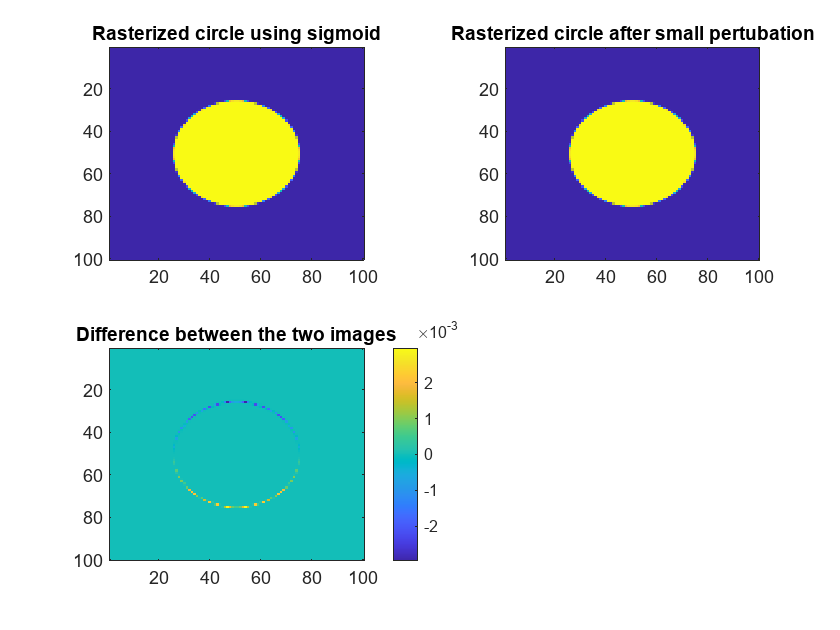

circle_image = stableSigmoid(dist_to_center);
circle_image_changed = stableSigmoid(dist_to_center_changed);

figure
nexttile
imagesc(circle_image)
title('Rasterized circle using sigmoid')
nexttile
imagesc(circle_image_changed)
title('Rasterized circle after small pertubation')
nexttile
imagesc(circle_image_changed - circle_image)
colorbar
title('Difference between the two images')

And that's it! We see that even a very small pertubation to our parameters results in a difference in the output image. This is the complete differentiable rasterization pipeline. To rasterize shapes other than circles, you simply need to use a different function to calculate the distance to the center. The function to do this for rectangles is included in the rendering function at the bottom of this live script.

## Optimizing rasterized shapes to approximate an image

Choose one of the following examples to see how we can optimize shape parameters to render an image as similar as possible to a target image.

example = "circles";
% example = "gaussians";
% example = "rectangles";

In *circles *example, we optimize the position, size and color of two circles to perfectly match a target image.

In gaussians example, we optimize the mean, sigma, and color of a large number of Gaussian functions to approximate a target image.

In rectangles example, we optimize the position, size and color of many rectangles to approximate a target image. 

### 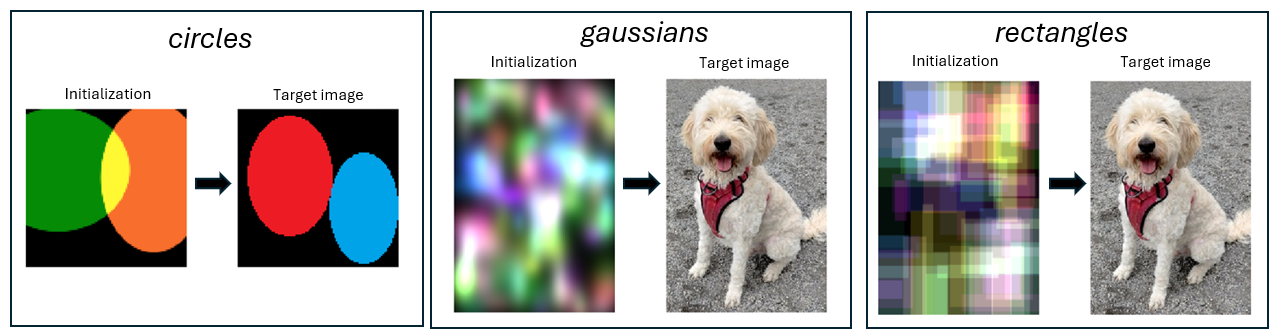

### Load a target image to approximate

Here we load the image we want to approximate with our shapes. We also pre-compute a grid of normalized pixel coordinates to be used in the rendering function. 

% Load target image
if strcmp(example, "rectangles") || strcmp(example, "gaussians")
    target_image = im2double(imread('bernie.jpg'));
elseif strcmp(example, "circles")
    target_image = im2double(imread('circle.png'));
end

% Convert to dlarray
target_image = dlarray(target_image, 'SSCB'); 

% Precompute a pixel grid
[image_height, image_width, ~, ~] = size(target_image);
[X, Y] = ndgrid(linspace(0,1,image_height), linspace(0,1,image_width));
X = dlarray(X, 'SSCB');
Y = dlarray(Y, 'SSCB');

### Define the main hyperparameters

The hyperparameters are the type of shape to use (rectangle, circle or Gaussian), and the number of them to use. 

switch example
    case "rectangles"
        % Select the type of shape and number of them to use
        shape_type = "rectangle";
        num_shapes = 75; 
    case "circles"
        shape_type = "circle"; 
        num_shapes = 2; 
    case "gaussians"
        shape_type = "gaussians";
        num_shapes = 150;
end

### Initialize the parameters

Start by choosing a random initialization of the shape parameters. *Note: To find a particularly good set of initial values one could repeat the random initialization process multiple times and choose the set that result in the lowest loss function. This is not implemented here*.

**The shapes are each parameterized by three variables:**

For **rectangles**, *center* is the coordinate of the center of the rectangle, *dimensions* is the width and height of the rectangle, and *color* is the RGB color.

For circle**s**, *center* is the coordinate of the center of the circle, *dimensions* is the width and height of the circle, and *color* is the RGB color.

For **Gaussians**, *center* is the coordinate of the center (i.e. the mean), *dimensions* is the standard deviation in the x and y directions, and *color* is the RGB color 

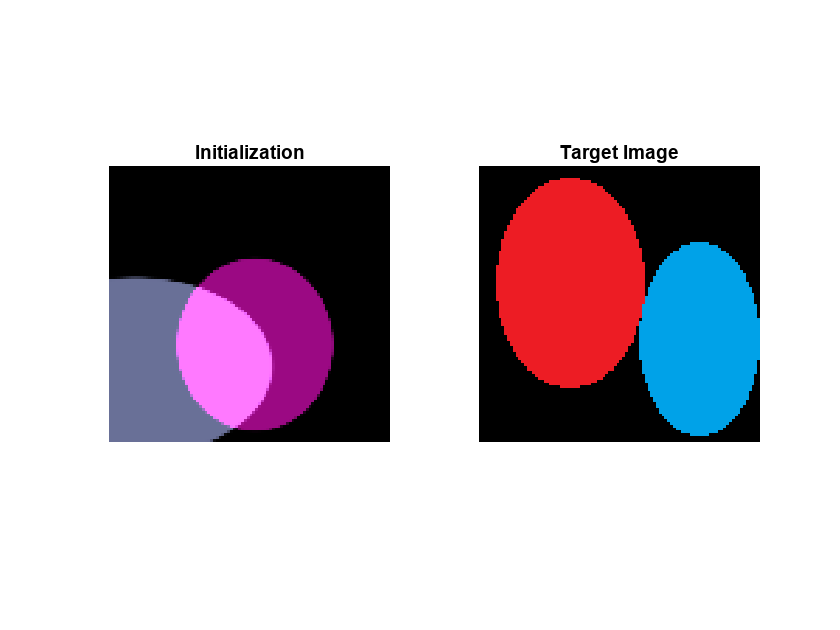

switch example
    case {"rectangles", "gaussians"}
    % Make a random initialization for the shape parameters
    % Values are chosen to be in a reasonable range
    center = dlarray(rand(2, num_shapes), 'CB'); 
    dimensions = dlarray(0.1 + rand(2, num_shapes) * 0.5, 'CB');
    color = dlarray(rand(3, num_shapes), 'CB');

    case "circles"
    % Make a random initialization for the shape parameters
    % Values are chosen to be in a reasonable range.

    % We set the two circles positions such that one will appear somewhere in the left side of
    % the image and one somewhere on the right side.

    center = dlarray([0.25, 0.25; 0, 0.5] + 0.5*rand(2, num_shapes), 'CB'); 
    dimensions = dlarray(0.5 + rand(2, num_shapes) * 0.5, 'CB'); 
    color = dlarray(rand(3, num_shapes), 'CB'); 
end

% Because the shapes colors are added to one another, the final
% render can have pixel values much greater than 1. 
% We normalize the initial colours to ensure the rendered image has the same 
% mean as the target image to help the optimization converge.
rendered_image = render(center, dimensions, color, X, Y, shape_type);
color = color .* (mean(target_image(:))/mean(rendered_image(:)));

% Plot the initialization render alongside the target image
figure
rendered_image = render(center, dimensions, color, X, Y, shape_type);

subplot(1, 2, 1);
imshow(extractdata(rendered_image));
title('Initialization');

subplot(1, 2, 2);
imshow(extractdata(target_image))
title('Target Image');

### Optimize

Set the optimization hyperparameters

% Set the learning rate. We use a slower learning rate for the circles
% example to more clearly visualize how it optimizes over time
switch example
    case {"rectangles", "gaussians"}
        learning_rate = 0.75;
    case "circles"
        learning_rate = 0.05;
end

% Multiplier for the learning rate to reduce it over time
decay_rate = 0.99;

% Total number of iterations
num_iterations = 125;

Optimize the shape parameters to fit the target image using SGDM

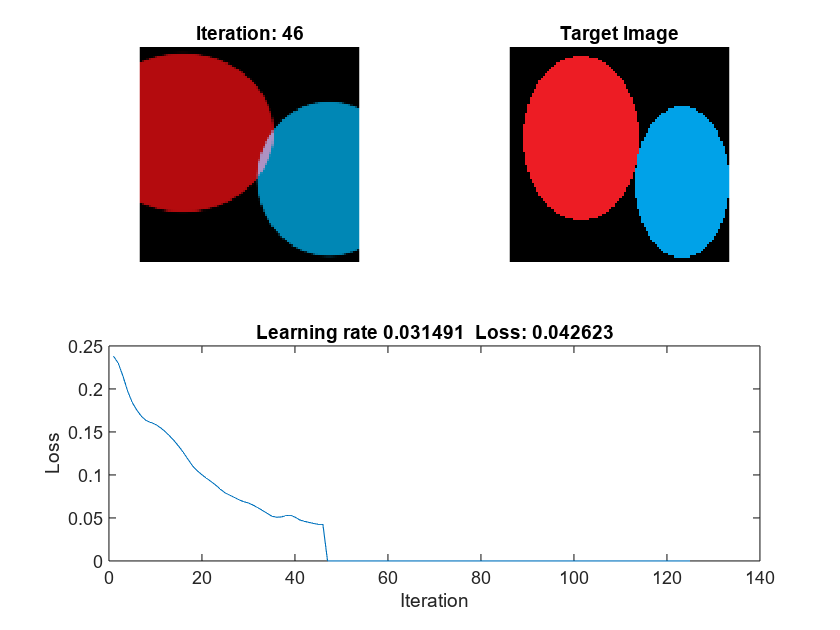

% Variables to store the loss function value over time, and the momentum
% vectors used by the sgdmupdate function 
losses = zeros(num_iterations,1);
v_center = [];
v_dimensions = [];
v_color = [];

for iter = 1:num_iterations
    % Compute gradients and loss value
    [gradients, loss_value] = dlfeval(@computeGradients, center, dimensions, color, target_image, X, Y, shape_type);

    % Extract the gradients
    grad_center = gradients{1};
    grad_dimensions = gradients{2};
    grad_color = gradients{3};

    % Update shape parameters using the sgdm optimizer
    [center, v_center] = sgdmupdate(center, grad_center, v_center, learning_rate);
    [dimensions, v_dimensions] = sgdmupdate(dimensions, grad_dimensions, v_dimensions, learning_rate);
    [color, v_color] = sgdmupdate(color, grad_color, v_color, learning_rate);

    % Clip the parameters to ensure they stay within reasonable bounds
    center = clip(center, 0.01, 0.99);
    dimensions = clip(dimensions, 0.01, 1);

    % Reduce the learning rate over time to make smaller adjustments at
    % later iterations
    learning_rate = learning_rate * decay_rate;

    % Store the cost function
    losses(iter) = extractdata(loss_value);

    % Plot the rendered image alongside the target image
    rendered_image = render(center, dimensions, color, X, Y, shape_type);
    
    subplot(2, 2, 1);
    imshow(extractdata(rendered_image));
    title(['Iteration: ', num2str(iter)]);
    
    subplot(2, 2, 2);
    imshow(extractdata(target_image));
    title('Target Image');
    
    subplot(2, 2, [3, 4]);
    plot(losses);
    xlabel('Iteration');
    ylabel('Loss');
    title("Learning rate " + string(learning_rate)  + "  Loss: "+string(extractdata(loss_value)));

    drawnow;
end

### Supporting functions

**Loss function**

function loss = computeLoss(center, dimensions, color, target_image, X, Y,  shape_type)
    % Render the image given the current shape parameters, and then
    % calculate the mean-square-error of the render compared to the target
    % image.
    rendered_image = render(center, dimensions, color, X, Y, shape_type);
    loss = mean((rendered_image(:) - target_image(:)).^2);
end

**Function to compute gradients with respect to shape parameters**

function [gradients, loss_value] = computeGradients(center, dimensions, color, target_image, X, Y, shape_type)
    % Evaluate the loss function and the gradient with respect to the shape
    % parameters
    loss_value = computeLoss(center, dimensions, color, target_image, X, Y, shape_type);
    gradients = dlgradient(loss_value, {center, dimensions, color});
end

**The differentiable rendering function**

The edges of the shapes are blurred using a sigmoid function which makes the rasterization continuous and differentiable. Different shapes are defined using different signed distance functions. 

function rendered_image = render(center, dimensions, color, X, Y, shape_type)
    % This function takes the shape parameters, pixel grids, and shape type
    % and then outputs the final rendered image.

    % It uses the same process as detailed in the 'Differentiable rendering introduce'
    % section, but the code is vectorized to perform all the steps for all
    % shapes simultaneously for speed.

    switch shape_type
    case "rectangle"
        % Render each rectangle using the signed distance function followed
        % by the sigmoid function. 
        dist_to_center = max(abs(X - reshape(center(1,:), 1, 1,1, [])) ./ (0.5 * reshape(dimensions(1,:), 1, 1,1, [])), ...
                         abs(Y - reshape(center(2,:), 1, 1,1, [])) ./ (0.5 * reshape(dimensions(2,:), 1, 1,1, [])));
        mask = stableSigmoid(dist_to_center);
    case "circle"
        % Render each circle using the signed distance function followed
        % by the sigmoid function
        dist_to_center =  (X - reshape(center(1,:), 1, 1,1, [])).^2 ./ ((0.5 * reshape(dimensions(1,:), 1, 1,1, [])).^2 + 1e-8) ...
                        + (Y - reshape(center(2,:), 1, 1,1, [])).^2 ./ ((0.5 * reshape(dimensions(2,:), 1, 1,1, [])).^2 + 1e-8);
        mask = stableSigmoid(dist_to_center);
    case "gaussians"
        % Render each gaussian. This does not require signed distance
        % functions or sigmoids -- we just use the standard formula for a
        % 2D Gaussian.
        mask = exp(-((X - reshape(center(1,:), 1, 1,1, [])).^2 ./ (0.02 * reshape(dimensions(1,:), 1, 1,1, [])) + ...
                               (Y - reshape(center(2,:), 1, 1,1, [])).^2 ./ (0.02 * reshape(dimensions(2,:), 1, 1,1, []))));
    end

    % Combine each of the shapes into one image with additive blending
    % Different blending types will give different results!
    rendered_image = sum(mask .* reshape(color, 1, 1, size(color, 1), []), 4);
end

**Stable sigmoid function**

% Stable sigmoid function for smooth edge approximation
function y = stableSigmoid(x)
    y = 1 ./ (1 + exp(-clip(150 * (1-x),-20,20)));
    y = clip(y, 1e-6, 1-1e-6);
end


*Copyright 2024 The MathWorks, Inc.*